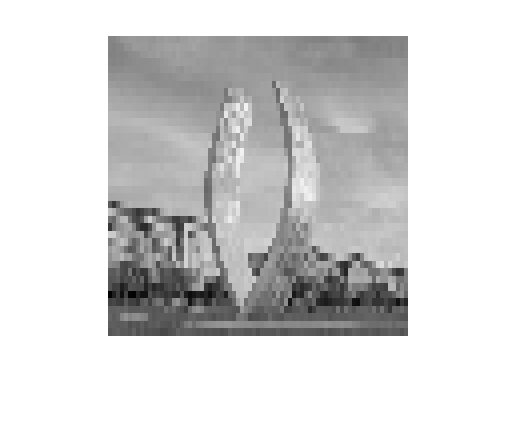

% Obtaining necessary images 
originalImage = im2uint8(imread('Original-Image.tif'));

down_sampled_nni = my_im_resize(originalImage, [40, 75], 'nearest');
imwrite(down_sampled_nni,'down_sampled_nni', 'png');

down_sampled_bli = my_im_resize(originalImage, [40, 75], 'bilinear');
imwrite(down_sampled_bli,'down_sampled_bli', 'png');

up_sampled_nni = my_im_resize(originalImage, [425, 600], 'nearest');
imwrite(up_sampled_nni,'up_sampled_nni', 'png');

up_sampled_bli = my_im_resize(originalImage, [425, 600], 'bilinear');
imwrite(up_sampled_bli,'up_sampled_bli', 'png');

% Reconstructing Images
reconstructed_down_sampled_nni = my_im_resize(down_sampled_nni, [300, 300], 'nearest');
imshow(reconstructed_down_sampled_nni, [0, 255]);

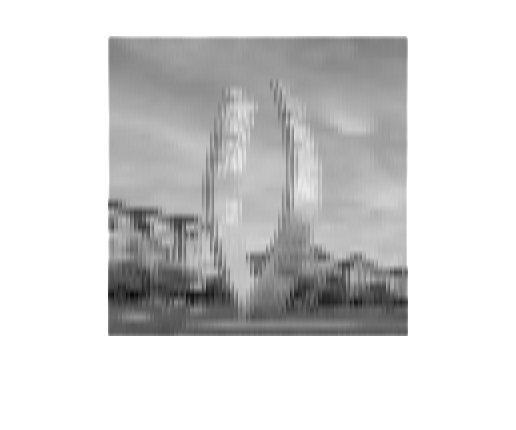


reconstructed_down_sampled_bli = my_im_resize(down_sampled_bli, [300, 300], 'bilinear');
imshow(reconstructed_down_sampled_bli, [0, 255]);

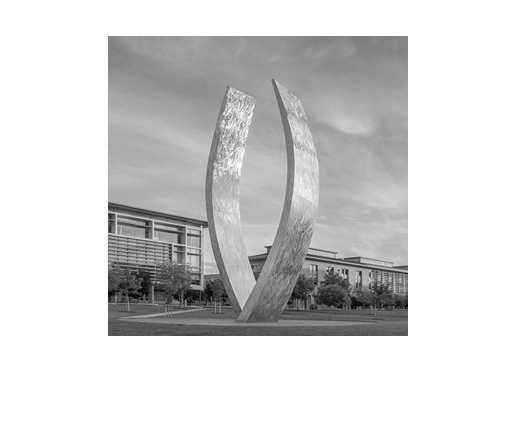


reconstructed_up_sampled_nni = my_im_resize(up_sampled_nni, [300, 300], 'nearest');
imshow(reconstructed_up_sampled_nni, [0, 255]);

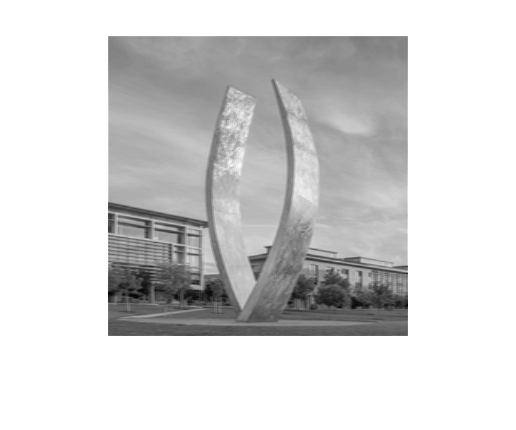


reconstructed_up_sampled_bli = my_im_resize(up_sampled_bli, [300, 300], 'bilinear');
imshow(reconstructed_up_sampled_bli, [0, 255]);


% Obtaining RMSEs
RMSE_1 = my_RMSE(originalImage, reconstructed_down_sampled_nni);
RMSE_2 = my_RMSE(originalImage, reconstructed_down_sampled_bli);
RMSE_3 = my_RMSE(originalImage, reconstructed_up_sampled_nni);
RMSE_4 = my_RMSE(originalImage, reconstructed_up_sampled_bli);

% Entry Point
% Function decides which interpolation method to use to resize the image 

function resized_img = my_im_resize(orig_img, new_img_dims, mode)
    % Creating matrix that will represent resized image
    resized_img = zeros(new_img_dims, 'uint8');

    if strcmp(mode, 'nearest')
        resized_img = my_nearest_neighbor(orig_img, resized_img);

    elseif strcmp(mode, 'bilinear') 
	resized_img = my_bilinear(orig_img, resized_img);
    end
end


% Function resizes a provided image using nearest neighbor interpolation 
function resized_img = my_nearest_neighbor(orig_img, resized_img)
    [orig_img_ht, orig_img_wd]       = size(orig_img);
    [resized_img_ht, resized_img_wd] = size(resized_img);

    % Executing nearest neighbor interpolation algorithm 
    for x = 1 : resized_img_ht
        for y = 1 : resized_img_wd
	   % Mapping pixel at location (x,y) in resized image to corresponding pixel in original image
	   [mx, my] = pixel_mapper(orig_img_ht, orig_img_wd, resized_img_ht, resized_img_wd, x, y, 'rounded');

	   % Assigning intensity to pixel in resized image
	   resized_img(x,y) = orig_img(mx, my);
	end
    end
end

% Function resizes a provided image using bilinear interpolation 
function resized_img = my_bilinear(orig_img, resized_img)
    [orig_img_ht, orig_img_wd]       = size(orig_img);
    [resized_img_ht, resized_img_wd] = size(resized_img);

    % Executing bilinear interpolation algorithm
    for x = 1 : resized_img_ht
        for y = 1 : resized_img_wd
	   % Mapping pixel at location (x, y) in resized image to corresponding pixel in original image
	   [mx, my] = pixel_mapper(orig_img_ht, orig_img_wd, resized_img_ht, resized_img_wd, x, y, 'non-rounded');

	   % Finding the 4 nearest neighbors of the mapped pixel
	   [nr_top_nbr, nr_btm_nbr] = find_nearest_neighbors(mx, orig_img_ht);	% Nearest vertical neighbors 
	   [nr_lt_nbr, nr_rt_nbr]	 = find_nearest_neighbors(my, orig_img_wd);	% Nearest horizontal neighbors

	   % Finding intensity values of nearest neighbors
	   top_lt_i = orig_img(nr_top_nbr, nr_lt_nbr);
	   top_rt_i = orig_img(nr_top_nbr, nr_rt_nbr);
	   btm_lt_i = orig_img(nr_btm_nbr, nr_lt_nbr);
	   btm_rt_i = orig_img(nr_btm_nbr, nr_rt_nbr);

	   % Assigning intensity to the pixel in the resized image
	   resized_img(x, y) = my_bilinear_helper(nr_top_nbr, nr_btm_nbr, nr_lt_nbr, nr_rt_nbr, top_lt_i, top_rt_i, btm_lt_i, btm_rt_i, mx, my);
        end
    end
end


% Function maps pixels from resized image to original image
% Function returns mapped coordinates 
function [mx, my] = pixel_mapper(orig_img_ht, orig_img_wd, resized_img_ht, resized_img_wd, x, y, mode)
    if strcmp(mode, 'rounded')
	mx = round((orig_img_ht / resized_img_ht) * (x - 0.5) + 0.5);
	my = round((orig_img_wd / resized_img_wd) * (y - 0.5) + 0.5);

    elseif strcmp(mode, 'non-rounded')
	mx = (orig_img_ht / resized_img_ht) * (x - 0.5) + 0.5;
	my = (orig_img_wd / resized_img_wd) * (y - 0.5) + 0.5;
    end
end


% Function finds the nearest horizontal or vertical neighbors of the provided position 
% If provided mx and resized image height --> returns top and bottom neighbor
% If provided my and resized image width  --> return left and right neighbor 
function [nr_nbr_1, nr_nbr_2] = find_nearest_neighbors(pos, dim_max)
    % Checking if the provided position is an integer 
    if isreal(pos) && rem(pos, 1) == 0
        nr_nbr_1 = pos;
	nr_nbr_2 = pos;

    elseif pos < 1
	nr_nbr_1 = 1;
	nr_nbr_2 = 2;

    elseif pos > dim_max
	nr_nbr_1 = dim_max - 1;
	nr_nbr_2 = dim_max;

    else
	nr_nbr_1 = floor(pos);
	nr_nbr_2 = ceil(pos);
    end
end 


% Function performs the 3 main operations in bilinear interpolation that determine the intesity value of a pixel in a resized image
function intensity = my_bilinear_helper(nr_top_nbr, nr_btm_nbr, nr_lt_nbr, nr_rt_nbr, top_lt_i, top_rt_i, btm_lt_i, btm_rt_i, mx, my)
    i1 = (((nr_lt_nbr - my) / (nr_lt_nbr - nr_rt_nbr)) * top_lt_i) + (((my - nr_rt_nbr) / (nr_lt_nbr - nr_rt_nbr)) * top_rt_i);
    i2 = (((nr_lt_nbr - my) / (nr_lt_nbr - nr_rt_nbr)) * btm_lt_i) + (((my - nr_rt_nbr) / (nr_lt_nbr - nr_rt_nbr)) * btm_rt_i);

    intensity = (((nr_btm_nbr - mx) / (nr_btm_nbr - nr_top_nbr)) * i1) + (((mx - nr_top_nbr) / (nr_btm_nbr - nr_top_nbr)) * i2);
end 


% Function computes the difference between two images
% "RMSE is commonly used to evaluate the effectiveness of image reconstructing algorithms by computing the pixelwise difference 
% between the original image and reconstructed image" (Shawn Newsam)
function RMSE = my_RMSE(orig_img, reconstructed_img)
    [imgs_ht, imgs_wd] = size(orig_img);

    RMSE = orig_img - reconstructed_img;
    RMSE = RMSE.^2;
    RMSE = sum(RMSE(:));
    RMSE = RMSE / (imgs_ht * imgs_wd);
    RMSE = sqrt(RMSE);
end







